# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

## Reset del workspace

addpath ..\'D-STEM v2.1'\Src\
clear all %#ok<CLALL> 
clc

## Creazione dei grafici per il capitolo 1

### Generazione delle spline di Fourier

#### Scelta dei parametri

t_start = 0;
t_end = 23;
nbasis = 5;
exp_path = "..\Tesi\Immagini";
exp_spline_plot = false;

#### Visualizzazione delle singole funzioni base (coef. unitari)

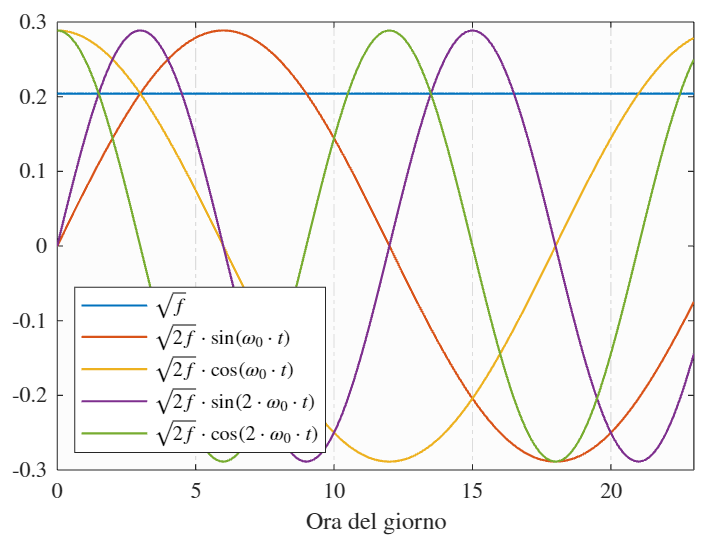

basis_obj = create_fourier_basis([0, t_end+1], nbasis);
t_domain = t_start:.1:t_end;
basis_eval = full(getbasismatrix(t_domain, basis_obj));

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
plot(t_domain, basis_eval(:, 1), 'LineWidth', 1)
hold on
for i=2:nbasis
    plot(t_domain, basis_eval(:, i), 'LineWidth', 1)
end
hold off

xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$\sqrt{f}$", ...
        "$\sqrt{2f}\cdot\sin(\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\cos(\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$", ...
        "$\sqrt{2f}\cdot\cos(2\cdot\omega_0\cdot t)$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-.';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];

if exp_spline_plot
    exportgraphics(t, exp_path + "\1. Modello base\Basi Fourier.pdf");
end

#### Visualizzazione delle singole funzioni base (coef. non costanti)

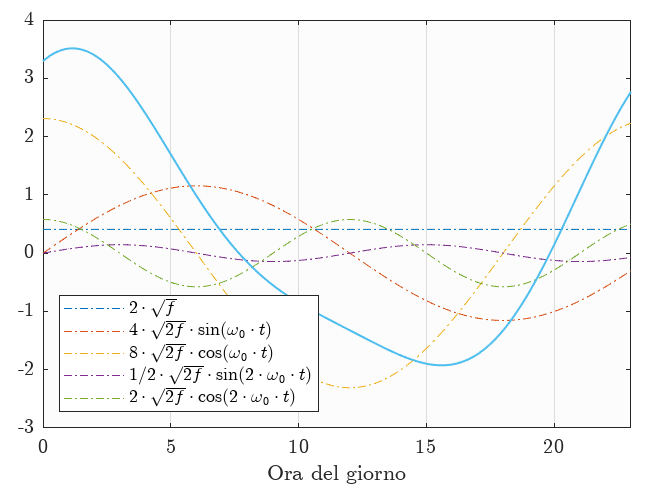

basis_eval_coef = repmat([2, 4, 8, .5, 2], size(t_domain, 2), 1).*basis_eval;

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact'); %#ok<*NASGU>
nexttile
plot(t_domain, basis_eval_coef(:, 1), 'LineWidth', .5, 'LineStyle', '-.')
hold on
for i=2:nbasis
    plot(t_domain, basis_eval_coef(:, i), 'LineWidth', .5, 'LineStyle', '-.')
end
plot(t_domain, sum(basis_eval_coef(:, :), 2), 'LineWidth', 1)
hold off

xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$2\cdot\sqrt{f}$", ...
        "$4\cdot\sqrt{2f}\cdot\sin(\omega_0\cdot t)$", ...
        "$8\cdot\sqrt{2f}\cdot\cos(\omega_0\cdot t)$", ...
        "$1/2\cdot\sqrt{2f}\cdot\sin(2\cdot\omega_0\cdot t)$", ...
        "$2\cdot\sqrt{2f}\cdot\cos(2\cdot\omega_0\cdot t)$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];

if exp_spline_plot
    exportgraphics(t, exp_path + ...
        "\1. Modello base\Spline Fourier con coefficienti non unitari.pdf"); %#ok<*UNRCH> 
end

#### Confronto tra spline (coef. unitari)

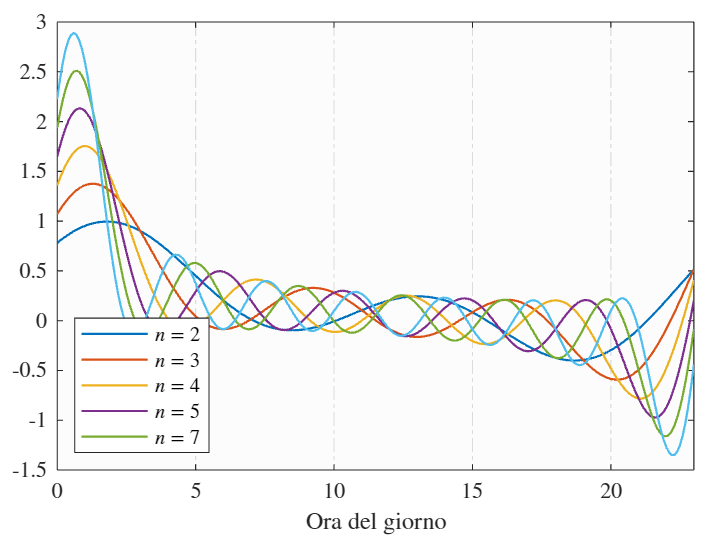

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
for i=5:2:15
    basis_obj_2 = create_fourier_basis([0, t_end+1], i);
    basis_eval_2 = full(getbasismatrix(t_domain, basis_obj_2));
    plot(t_domain, sum(basis_eval_2(:, :), 2), 'LineWidth', 1)
    if i == 5
        hold on
    end
end
hold off

xlim([0 23])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Ora del giorno", 'Interpreter', 'latex')
axs.YAxis.TickLabelInterpreter = 'latex';
legend(["$n = 2$", ...
        "$n = 3$", ...
        "$n = 4$", ...
        "$n = 5$", ...
        "$n = 7$"], ...
        'Location', 'southwest', 'Interpreter', 'latex')
grid on
axs.GridLineStyle = '-.';
axs.YGrid = "off";
axs.Color = [252/255, 252/255, 252/255];

if exp_spline_plot
    exportgraphics(t, exp_path + "\1. Modello base\Spline Fourier.pdf");
end

### Simulazione di un processo gaussiano

#### Scelta dei parametri

x1 = 50;
x2 = 55;
theta = 2;
exp_gauss_plot = false;

#### Costruzione della griglia e simulazione del processo

x = 0:1:99;
y = 0:1:99;
[X, Y] = meshgrid(x, y);
coord = [X(:) Y(:)];
x1_index = find(coord(:, 1) == x1 & coord(:, 2) == x1);
x2_index = find(coord(:, 1) == x2 & coord(:, 2) == x2);

dist = pdist2(coord, coord, "euclidean");
sp_corr = exp(-dist/theta);

rng('default')
v = mvnrnd(zeros(1, size(dist,1)), sp_corr);
v = reshape(v, size(X));

#### Visualizzazione del processo gaussiano

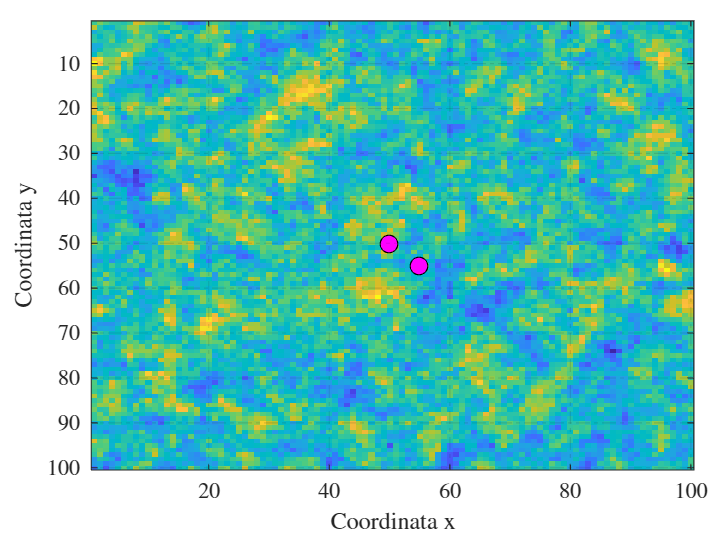

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
imagesc(v)
hold on
plot(x1, x1, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'black');
plot(x2, x2, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'black');
hold off

xlabel("Coordinata x", 'Interpreter', 'latex');
ylabel("Coordinata y", 'Interpreter', 'latex');
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
axs.YAxis.TickLabelInterpreter = 'latex';
grid on
axs.GridLineStyle = '-.';

if exp_gauss_plot
    exportgraphics(t, exp_path + "\1. Modello base\Sim. proc. gaussiano, " + ...
        "theta = " + num2str(theta) + ".pdf");
end

#### Visualizzazione della densità di probabilità congiunta di due v.c.

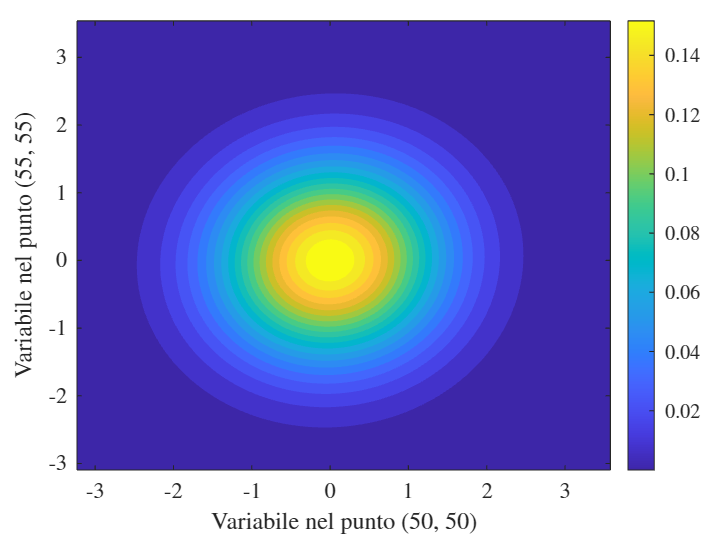

mu = [0 0];
sigma = [1 sp_corr(x1_index, x2_index); sp_corr(x1_index, x2_index) 1];

rng("default");
data = mvnrnd(mu, sigma, 1000);

x = linspace(min(data(:,1)), max(data(:,1)), 100);
y = linspace(min(data(:,2)), max(data(:,2)), 100);
[X, Y] = meshgrid(x, y);

Z = mvnpdf([X(:) Y(:)], mu, sigma);
Z = reshape(Z, size(X));

figure;
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
contourf(X, Y, Z, 20, 'LineColor', 'none');

xlabel("Variabile nel punto (" + num2str(x1) + ", " +  num2str(x1) + ")", 'Interpreter', 'latex');
ylabel("Variabile nel punto (" + num2str(x2) + ", " +  num2str(x2) + ")", 'Interpreter', 'latex');
axs = gca;
colorbar(axs, 'eastoutside', 'TickLabelInterpreter', 'latex');
axs.XAxis.TickLabelInterpreter = 'latex';
axs.YAxis.TickLabelInterpreter = 'latex';

if exp_gauss_plot
    exportgraphics(t, exp_path + "\1. Modello base\Sim. var. casuali, " + ...
        "theta = " + num2str(theta) + ".pdf");
end

## Simulazione di dati funzionali spazio-temporali

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

### **Scelta aleatoria dei punti spaziali**

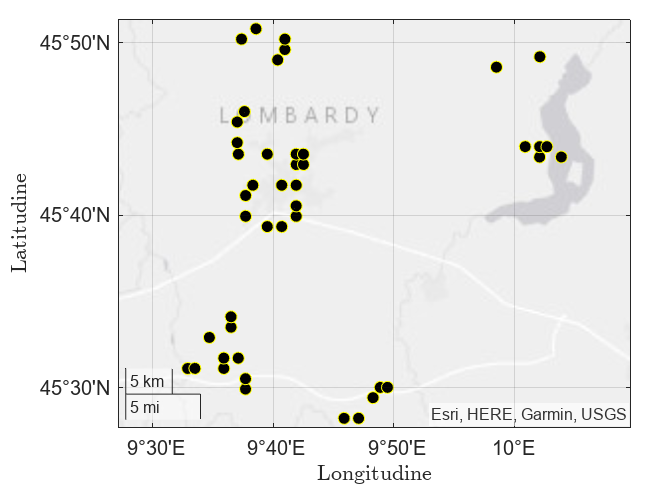

town_names = ["Bergamo" "Treviglio" "San Pellegrino Terme", ...
    "Sovere" "Sorisole" "Antegnate" "Parzanica"];
town_n_points = [15 10 5 2 3 5 5];

rng('default')
points = FSIM.get_points(town_names, town_n_points);
points = sortrows(points, {'Latitude', 'Longitude'});

figure;
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
fig = geoscatter(points, "Latitude", "Longitude", "filled", "MarkerFaceColor", "k", "MarkerEdgeColor", "y");
fig.Parent.LatitudeLabel.Interpreter = "latex";
fig.Parent.LatitudeLabel.String = "Latitudine";
fig.Parent.LongitudeLabel.Interpreter = "latex";
fig.Parent.LongitudeLabel.String = "Longitudine";

% exportgraphics(t, exp_path + "\2. Nuovo modello\Mappa stazioni simulate.pdf")

### Scelta dei parametri

q = 24;
n = sum(town_n_points);
T = 365;
params.rho = .01;
n_basis.p_eps = 5;
params.c_eps = [2; -2; -10; .5; 2];
n_basis.p_beta = 5;
params.c_beta = [2; 4; 8; .5; 2];
n_basis.p_z = 5;
params.theta = [.05; .05; .05; .05; .05];

rng('default')
obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [45 24 1 365]
- p_eps, p_beta and p_z: [5 5 5]
 
Parameters set: 
- rho: 0.01
- c_eps: [2           -2          -10          0.5            2]
- c_beta_1: [2           4           8         0.5           2]
- diag_G: [0.25806     0.40872      0.5949     0.26221     0.60284]
- diag_V: [8  3  2  3  4]
- theta: [0.05        0.05        0.05        0.05        0.05]


### Avvio della/e simulazione/i

rng('default')
obj = obj.run(10);

Running simulation/s: 
- sim. 1 of 10 done.
- sim. 2 of 10 done.
- sim. 3 of 10 done.
- sim. 4 of 10 done.
- sim. 5 of 10 done.
- sim. 6 of 10 done.
- sim. 7 of 10 done.
- sim. 8 of 10 done.
- sim. 9 of 10 done.
- sim. 10 of 10 done.


**NB**: si ricorda che le osservazioni $Y_{sim}$ sono impilate prima per $q$, poi per $n$ (fissato $q$, viene espresso il valore di $y$ assunto presso le diverse $n$ stazioni).

### Formattazione dei dati per rispettare la sintassi di D-STEM

data = obj.format_data;

Running data formatting: 
- dataset 1 of 10 done.
- dataset 2 of 10 done.
- dataset 3 of 10 done.
- dataset 4 of 10 done.
- dataset 5 of 10 done.
- dataset 6 of 10 done.
- dataset 7 of 10 done.
- dataset 8 of 10 done.
- dataset 9 of 10 done.
- dataset 10 of 10 done.


### Stima del modello spazio-temporale

#### Definizione della tipologia di modello

o_modeltype = stem_modeltype('f-HDGM');
if obj.params.rho == 0
    o_modeltype.flag_potential = false;
else
    o_modeltype.flag_potential = true;
end

#### Configurazione delle basi

input_fda.spline_type = 'Fourier';
input_fda.spline_range = [0 q];
input_fda.spline_nbasis_z = n_basis.p_z;
input_fda.spline_nbasis_beta = n_basis.p_beta; 
input_fda.spline_nbasis_sigma = n_basis.p_eps;
o_fda = stem_fda(input_fda);

#### Dati in input

input_data.stem_modeltype = o_modeltype;
input_data.data_table = data{1};
input_data.stem_fda = o_fda;
o_data = stem_data(input_data);

 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=45
 
Number of time steps: T=365
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


#### Inizializzazione dei parametri

o_par = stem_par(o_data, 'exponential');

if obj.params.rho ~= 0
    o_par.rho = obj.params.rho;
end
o_model = stem_model(o_data, o_par);

Generating data matrices...
Generation ended.


o_par.beta = obj.params.c_beta;
o_par.sigma_eps = obj.params.c_eps;
o_par.theta_z = obj.params.theta';
o_par.G = diag(obj.params.diag_G);
o_par.v_z = diag(obj.params.diag_V);
o_model.set_initial_values(o_par);

#### Stima del modello

o_EM_options = stem_EM_options();
o_EM_options.exit_tol_par = 0.0001; 
o_EM_options.exit_tol_loglike = 0.0001; 
o_EM_options.max_iterations = 100;

o_model.EM_estimate(o_EM_options);

Generating point distance matrices...
Generation ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=1080
sum of sites for each variable: N=45
 
Date and time steps:
  Stating date  : 01-Jan-2023
  Ending date   : 31-Dec-2023
  Temporal steps: 365
 
Bounding box of the point data:
  Latitude min : 45.47 deg
  Latitude max : 45.85 deg
  Longitude min: 09.55 deg
  Longitude max: 10.07 deg
 
Number of latent variables: p=5
 
Covariates related to beta:
    {'const'}

************************
Iteration 1 started...
************************
  E step started...
    Kalman smoother started...
    Kalman smoother ended in 11.97s
    Xbeta evaluation started...
    Xbeta evaluation ended in 0.00s
    Conditional E, Var, Cov evaluation started...
   

## Previsione spaziale via kriging

#### Importazione e processamento dei confini amministrativi di una provincia

province = "BG";

province_shape = shaperead("Confini amministrativi\Provincie italiane\ProvCM01012023_g_WGS84.shp");
for i = 1:length(province_shape)
    if strcmp(province_shape(i).SIGLA, 'BG')
        shape = province_shape(i);
        break;
    end
end

Conversione delle coordinate da WGS84 UTM32N a gradi

[shape.Y, shape.X] = projinv(shapeinfo("Confini amministrativi\Provincie italiane\ProvCM01012023_g_WGS84.shp").CoordinateReferenceSystem, ...
    shape.X, shape.Y);
[shape.BoundingBox(:, 2), shape.BoundingBox(:, 1)] = projinv(shapeinfo("Confini amministrativi\Provincie italiane\ProvCM01012023_g_WGS84.shp").CoordinateReferenceSystem, ...
    shape.BoundingBox(:, 1), shape.BoundingBox(:, 2));

#### Costruzione della griglia

res = .004;
lat = shape.BoundingBox(1, 2):res:shape.BoundingBox(2, 2);
lon = shape.BoundingBox(1, 1):res:shape.BoundingBox(2, 1);
[lon_mat, lat_mat] = meshgrid(lon,lat);
krig_coordinates = [lat_mat(:) lon_mat(:)];

o_krig_grid = stem_grid(krig_coordinates, 'deg', 'regular', ...
    'pixel', size(lat_mat), 'square', res, res);
o_krig_data = stem_krig_data(o_krig_grid);
o_model.stem_data.shape = shape;
o_krig = stem_krig(o_model, o_krig_data);

#### Determinazione dei valori di $\mathbf{z}(\mathbf{s}, t)$ per ogni punto della griglia

o_krig_options = stem_krig_options();
o_krig_options.block_size = 30;
o_krig_options.back_transform = 0;
o_krig_options.no_varcov = 0;
o_krig_result = o_krig.kriging(o_krig_options);

Kriging started...
Kriging block 1 of 1147
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 15.18s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 20.14s
Kriging block 2 of 1147
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 13.63s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 18.13s
Kriging block 3 of 1147
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 11.72s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 16.08s
Krigin

#### Visualizzazione della mappa di potenziale

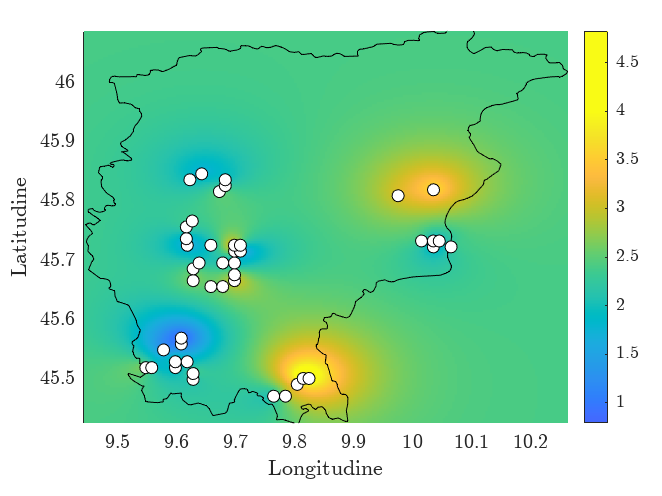

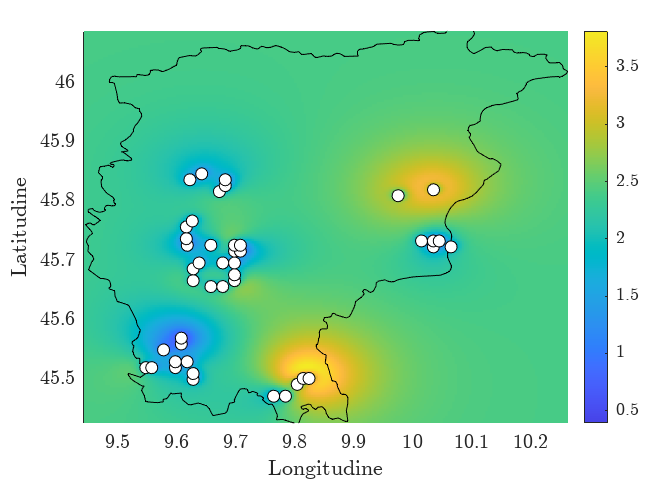

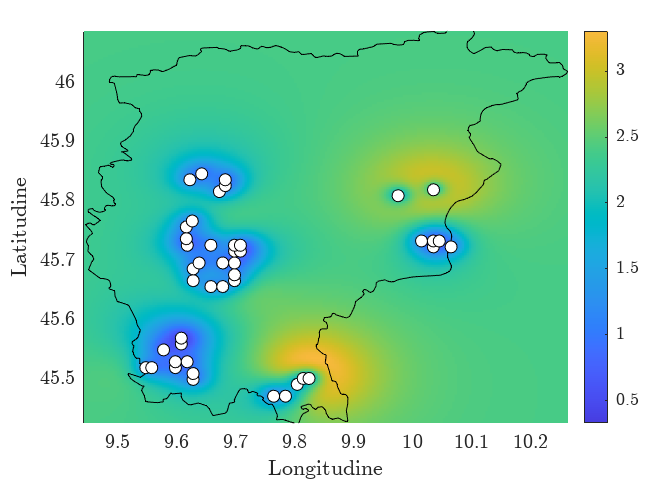

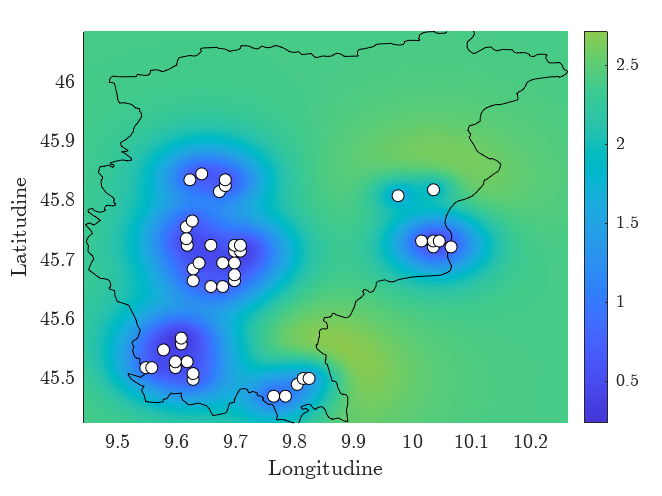

t = 50;
h = 4;
o_krig_result.shape = shape;
rho_to_test = [0 .005 .01 .02];
for i=1:length(rho_to_test)
    map_fig = o_krig_result.surface_plot(h, t, ones(size(lat_mat)), rho_to_test(i));
    % exportgraphics(map_fig, exp_path + "\2. Nuovo modello\Mappa potenziale, rho = " + num2str(rho_to_test(i)) + ".pdf")
end